## Lab 2.10

clear,clc
load lineup.mat
sound(y,8192)

(a)根据关系式确定回声信号he[n]

n = 0:1000
he = [1 zeros(1,999) 0.5]

(b)证明z[n]*he[n]是否等于y[n]，从而证明2.22式为2.21式的逆

%求出z[n]*he[n]
a = [1 zeros(1,999) 0.5]
b = 1   
z = filter(b,a,y)
y1 = conv(z,he)
%作图比较
figure
stem(1:7000,y )
hold on
stem(1:8000,y1,'r','+')
xlabel('n')
legend('y[n]','z[n]*h[n]')

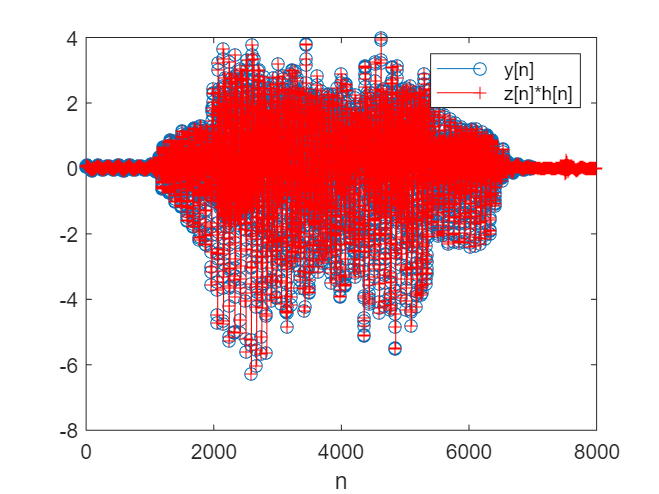

结论：由图可知，两信号相同，2.22式为2.21式的逆。

(c)定义her[n]

a = [1 zeros(1,999) 0.5]
b = 1  
d = [1 zeros(1,4000)]
her = filter(b,a,d )

(d)消除回声

z= filter(1,a,y )
figure
plot(z)
xlabel('n')
ylabel('z[n]')
sound(z,8192)

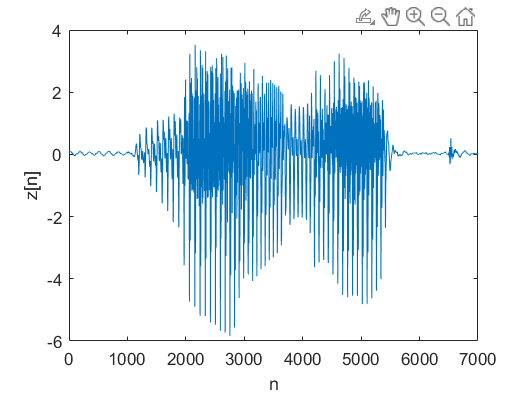

结论：音频不再听到回声。

(e) 绘制he[n]*her[n]，判断其和单位冲激函数是否相同。

hoa = conv(he,her)
plot(hoa)
ylabel('hoa[n]')
xlabel('n')

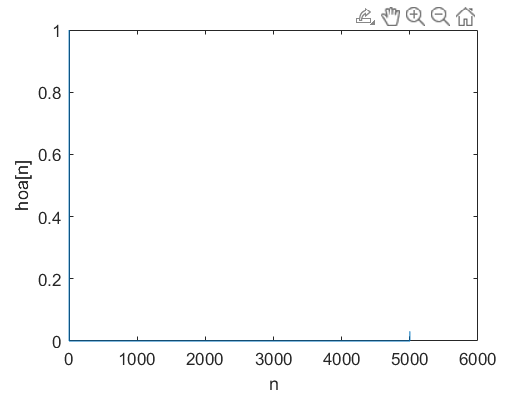

结论：卷积结果为一个有限的信号，而单位脉冲响应为无限信号。因为her信号不完整，只取了一部分。

(f)用信号的自相关确定N和alpha：通过自相关函数图像的性质，估计y2和y3的N和alpha。

%样例测试
clear,clc
NX = 100;
x = randn(1,NX);
N=50;
alpha = 0.9;
y = filter([1 zeros(1,N) alpha],1,x);
Ryy = conv(y,fliplr(y))
plot([-NX+1:NX-1],Ryy)

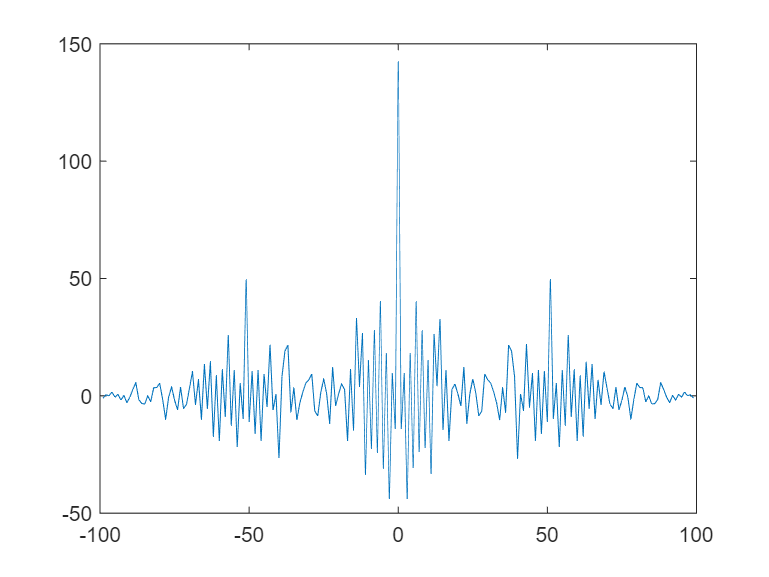

%求y2的N和alpha
load lineup.mat
nRyy = -length(y2)+1:length(y2)-1
Ryy = conv(y2,flipud(y2))
plot(nRyy,Ryy)
xlim([-4000 4000])

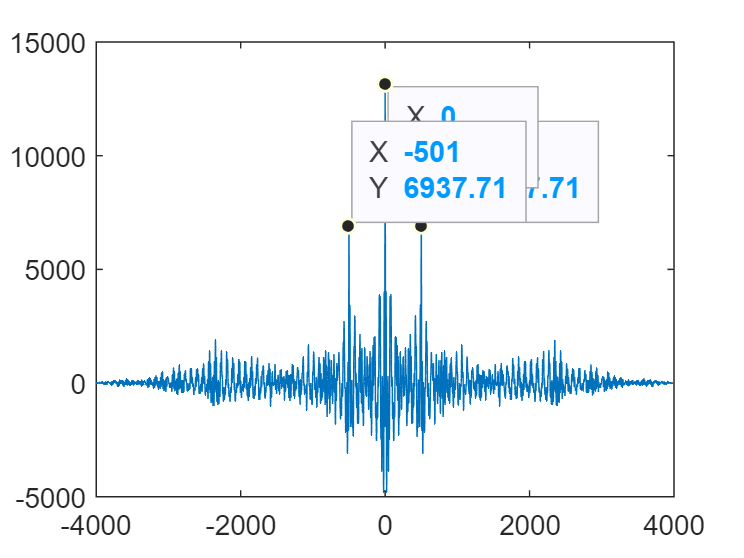

小结：如图，两次大值的X分别为501、-501，Y为6937.71，最大值的Y为13163，由计算可知N为501。由推导公式可知，(alpha^2+1)/alpaha = 13163/6937.71，求得alpha=0.949+0.316i或0.949-0.316i。

%估计y3的N1,alpha1,N2,alpha2
Ryy = conv(y3,flipud(y3))
nRyy = -length(y3)+1 : length(y3)-1
figure
plot(nRyy,Ryy)
xlim([-4000 4000])
xlabel('n')
ylabel('Ryy[n]')

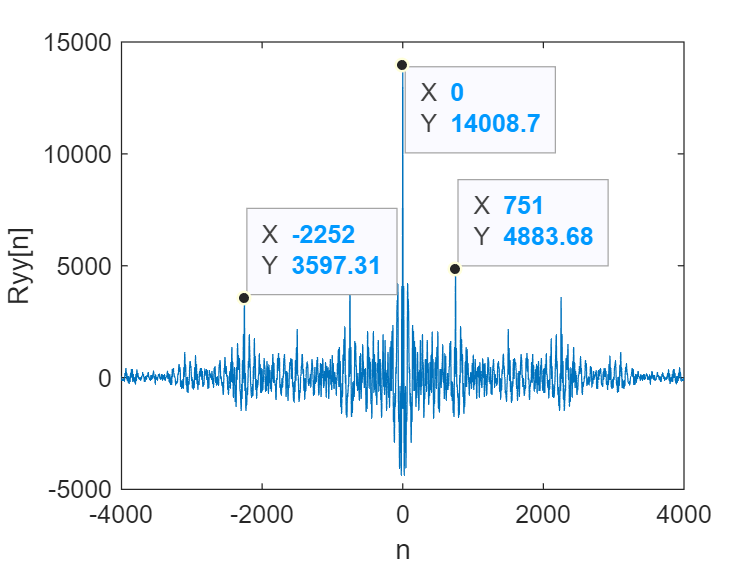

结论：由图可知，N1=751，N2=2252。

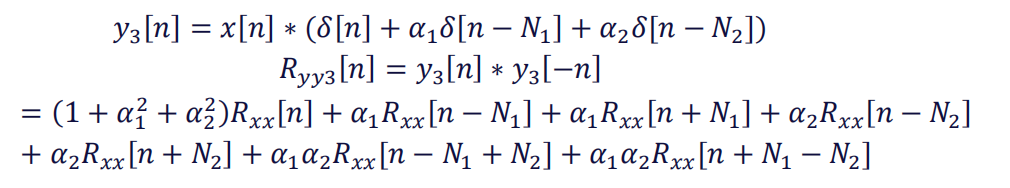

由以上公式计算得alpha1=0.599，alpha2=0.441。